# 04.초음파 센서를 사용하여 핸드폰과의 거리 변화에 따른 핸드폰의 이동속도의 변화를 추정하여 그래프로 나타내고 분석하시오.

# 1. Data Load

data = importdata('Assignment0304_이형섭_201901766.txt');

# 2. Ultra Sonic Sensor 값만 추출

d = data(:,2) % 플래쉬를 켠 핸드폰과의 거리(cm)

d =     85
    84
    83
    83
    83
    82
    82
    83
    81
    82


d = smoothdata(d) % 잡음이 있는 data의 평활화

d =    78.3824
   78.1714
   77.9167
   77.7027
   77.4474
   77.2051
   76.9750
   76.7561
   76.5000
   76.2558


# 3. 플래쉬를 움직인 속도 계산

dt = 0.05; % sampling한 시간 간격 (단위: sec)
dd = diff(d) % �LED의 변위 (단위 : cm)

dd =    -0.2109
   -0.2548
   -0.2140
   -0.2553
   -0.2422
   -0.2301
   -0.2189
   -0.2561
   -0.2442
   -0.2558



v = dd/dt % 거리를 sampling 시간으로 차분 (속도 = (이동거리)/(걸린시간)) -> 방향 존재

v =    -4.2185
   -5.0952
   -4.2793
   -5.1067
   -4.8448
   -4.6026
   -4.3780
   -5.1220
   -4.8837
   -5.1163


# 4. Graph 그리기(핸드폰의 이동속도 변화)

x = (0:length(d)-2) * 0.05

x =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000    2.0500    2.1000    2.1500    2.2000    2.2500    2.3000    2.3500    2.4000    2.4500


y = transpose(v)

y =    -4.2185   -5.0952   -4.2793   -5.1067   -4.8448   -4.6026   -4.3780   -5.1220   -4.8837   -5.1163   -4.4444   -4.6860   -5.3377   -4.2819   -4.9235   -4.7265   -4.5412   -5.1357   -4.5646   -4.7659   -4.9562   -5.1364   -5.3070   -5.1240   -5.2893   -5.4463   -5.2678   -5.4204   -5.2483   -5.0843   -5.5433   -5.3753   -5.2148   -5.6497  -10.2941   -9.7059  -10.0000  -10.2941  -10.2941  -10.2941  -10.5882  -10.8824  -10.8824  -10.8824  -11.4706  -11.4706  -11.7647  -12.0588  -12.0588  -11.7647


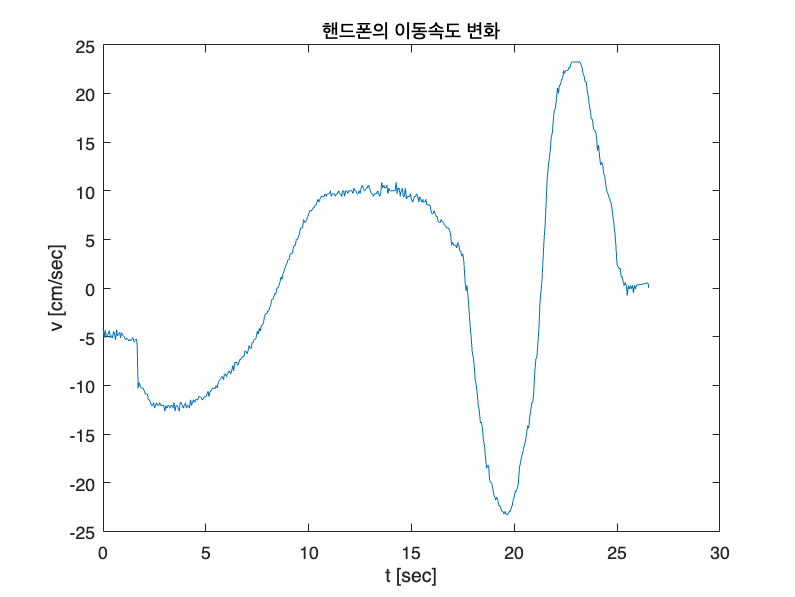


plot(x, y)           
xlabel('t [sec]');       % x축 label 설정 
ylabel('v [cm/sec]');    % y축 label 설정 (시간에 따른 속도)
title('핸드폰의 이동속도 변화'); 

# 5. 초당 핸드폰의 평균이동속도 추정

% 총 Sampling하는 시간 : total_t
% v를 0.5 초마다 평균이동속도를 추정할 것이다.
total_t = ceil(length(d) * 0.05) 

total_t = 27

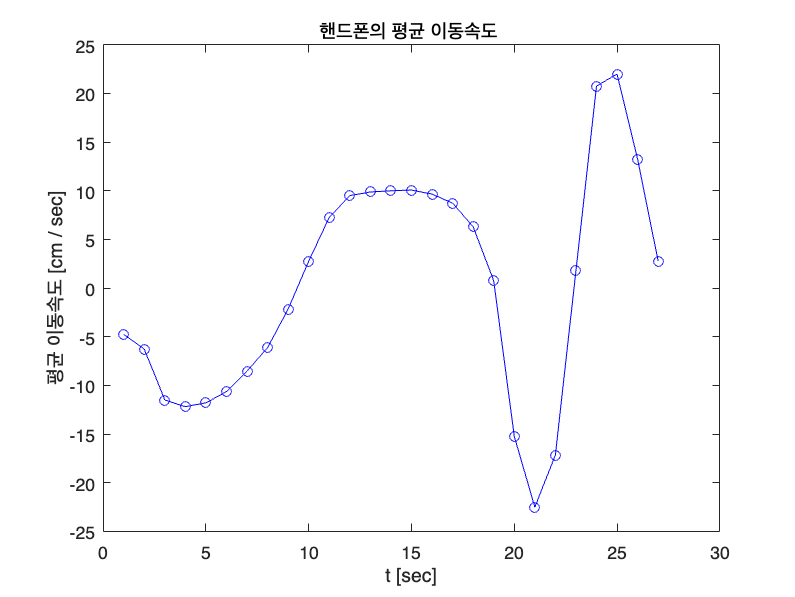


% 구간 길이 계산
interval_length = floor(length(d) / total_t);

% 평균 속도 계산
avg_speed = zeros(total_t, 1);
for i = 1:total_t
    start_idx = (i-1)*interval_length + 1;
    end_idx = i*interval_length;
    avg_speed(i) = mean(v(start_idx:end_idx));
end

% 그래프 출력
plot(avg_speed, 'bo-');
xlabel('t [sec]');
ylabel('평균 이동속도 [cm / sec]');
xlim([0, 30])
title('핸드폰의 평균 이동속도 ');